# Question 4

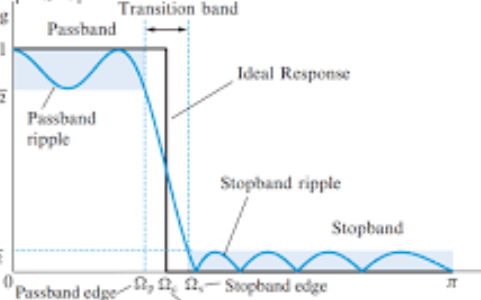

dp = 0.94, ds = 0.01, wp (digital)= 0.314 , ws = 1.57, 

wc = (0.314+1.57)/2 = 0.94

digital frequency = 2*pi*f / fs, where fs = sampling frequency = 2*max analog frequency.

Now we have all values in which domain ?

ans : digital domain

## Defining

syms n
wp = 0.314;
ws = 1.57;
wc = 0.94;

N = [10,25,50,70,100,500];
ideal_lpf = sin(wc*n)/(pi*n);

## Rectangular window

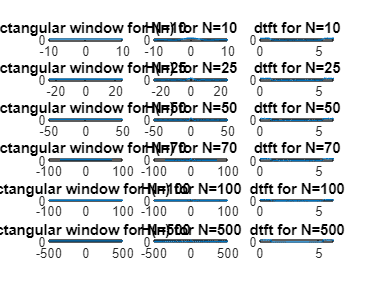

for index = 1:length(N)
    rect_window = ones(1,2*N(index)+1);
    n_subs = -N(index)+0.0001:N(index)+0.0001;
    practical_lpf = subs(ideal_lpf,n,n_subs);

    subplot(length(N),3,3*index-2)
    plot(-N(index):N(index),rect_window)
    title(['rectangular window for N=',num2str(N(index))])

    subplot(length(N),3,3*index-1)
    plot(n_subs-0.001,practical_lpf)
    title(['H(n) for N=',num2str(N(index))])

    signal_length = 2*N(index)+1;
    k = 0:signal_length+1000-1;
    wdtft = 2*pi*k/(signal_length+1000);
    dtft = fft(double(practical_lpf),signal_length+1000);
    %a = dtft(double(practical_lpf),-N(index):N(index),0:2*pi/signal_length:2*pi*(signal_length-1)/signal_length)
    subplot(length(N),3,3*index)
    plot(wdtft,abs(dtft))
    title(['dtft for N=',num2str(N(index))])
end

## Finding optimal N (Rect)

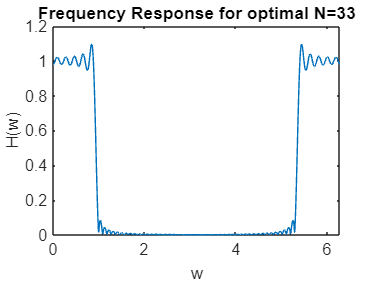

for i = 1:100

N_optimal_rect = i;
practical_lpf = subs(ideal_lpf,n,-N_optimal_rect+0.0001:N_optimal_rect+0.0001);
rect_window = -N_optimal_rect:N_optimal_rect;

signal_length = 2*N_optimal_rect+1;
k = 0:signal_length+1000-1;
wdtft = 2*pi*k/(signal_length+1000);
dtft = fft(double(practical_lpf),signal_length+1000);

clf
passes = evaluate(abs(dtft),wdtft);

if(passes==1)
    break
end
end

plot(wdtft,abs(dtft))
title(['Frequency Response for optimal N=',num2str(N_optimal_rect)])
ylabel('H(w)')
xlabel('w')

## Hann window

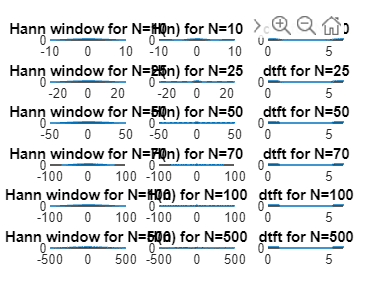

for index = 1:length(N)
    rect_window = ones(1,2*N(index)+1);
   
    %% Hann window
    n_hann = 0:2*N(index);
    hann_window = 0.5.*(1-cos((2.*pi.*n_hann)/(2*N(index)))).*rect_window;
    
    %% Truncated h(n)
    n_subs = -N(index)+0.0001:N(index)+0.0001;
    practical_lpf = subs(ideal_lpf,n,n_subs);

    %plotting hanning window
    subplot(length(N),3,3*index-2)
    plot(-N(index):N(index),hann_window)
    title(['Hann window for N=',num2str(N(index))])

    %plotting Truncated h(n)
    subplot(length(N),3,3*index-1)
    plot(n_subs-0.001,practical_lpf)
    title(['H(n) for N=',num2str(N(index))])

    signal_length = 2*N(index)+1;
    k = 0:signal_length+1000-1;
    wdtft = 2*pi*k/(signal_length+1000);

    % dtft of h(n)*hann window
    dtft = fft(double(practical_lpf.*hann_window),signal_length+1000);
    subplot(length(N),3,3*index)
    plot(wdtft,abs(dtft))
    title(['dtft for N=',num2str(N(index))])
end

## Finding optimal N (Hann)

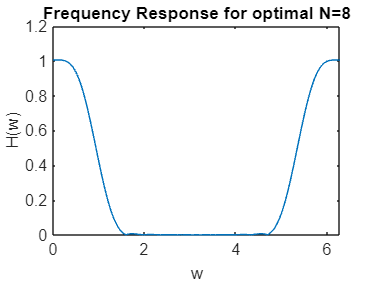

for i = 1:100

N_optimal_hann = i;
practical_lpf = subs(ideal_lpf,n,-N_optimal_hann+0.0001:N_optimal_hann+0.0001);
rect_window = ones(1,2*N_optimal_hann+1);

n_hann = 0:2*N_optimal_hann;
hann_window = 0.5.*(1-cos((2.*pi.*n_hann)/(2*N_optimal_hann))).*rect_window;

signal_length = 2*N_optimal_hann+1;
k = 0:signal_length+1000-1;
wdtft = 2*pi*k/(signal_length+1000);
dtft = fft(double(practical_lpf.*hann_window),signal_length+1000);

clf
passes = evaluate(abs(dtft),wdtft);

if(passes==1)
    break
end
end

plot(wdtft,abs(dtft))
title(['Frequency Response for optimal N=',num2str(N_optimal_hann)])
ylabel('H(w)')
xlabel('w')

## Hamming window

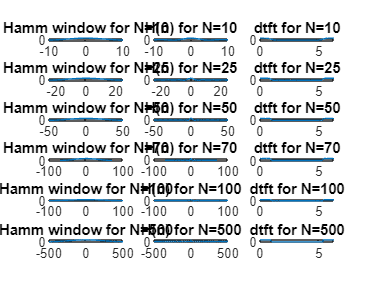

for index = 1:length(N)
    rect_window = ones(1,2*N(index)+1);
   
    %% Hann window
    n_hamm = 0:2*N(index);
    hamm_window = (0.54-0.46*cos((2.*pi.*n_hamm)/(2*N(index)))).*rect_window;
    
    %% Truncated h(n)
    n_subs = -N(index)+0.0001:N(index)+0.0001;
    practical_lpf = subs(ideal_lpf,n,n_subs);

    %plotting hamming window
    subplot(length(N),3,3*index-2)
    plot(-N(index):N(index),hamm_window)
    title(['Hamm window for N=',num2str(N(index))])

    %plotting Truncated h(n)
    subplot(length(N),3,3*index-1)
    plot(n_subs-0.001,practical_lpf)
    title(['H(n) for N=',num2str(N(index))])

    signal_length = 2*N(index)+1;
    k = 0:signal_length+1000-1;
    wdtft = 2*pi*k/(signal_length+1000);

    % dtft of h(n)*hamm window
    dtft = fft(double(practical_lpf.*hamm_window),signal_length+1000);
    subplot(length(N),3,3*index)
    plot(wdtft,abs(dtft))
    title(['dtft for N=',num2str(N(index))])
end

## Finding optimal N (Hamm)

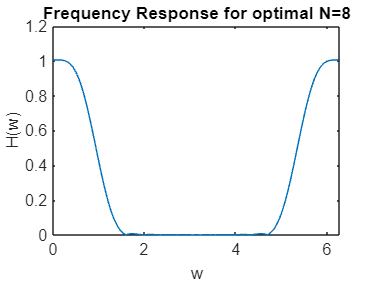

for i = 1:100

N_optimal_hamm = i;
practical_lpf = subs(ideal_lpf,n,-N_optimal_hamm+0.0001:N_optimal_hamm+0.0001);
rect_window = ones(1,2*N_optimal_hamm+1);

n_hamm = 0:2*N_optimal_hamm;
hamm_window = 0.5.*(1-cos((2.*pi.*n_hamm)/(2*N_optimal_hamm))).*rect_window;

signal_length = 2*N_optimal_hamm+1;
k = 0:signal_length+1000-1;
wdtft = 2*pi*k/(signal_length+1000);
dtft = fft(double(practical_lpf.*hamm_window),signal_length+1000);

clf
passes = evaluate(abs(dtft),wdtft);

if(passes==1)
    break
end
end

plot(wdtft,abs(dtft))
title(['Frequency Response for optimal N=',num2str(N_optimal_hamm)])
ylabel('H(w)')
xlabel('w')

## Blackman window

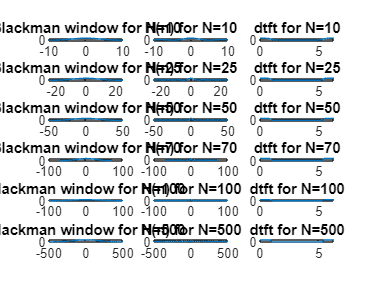

for index = 1:length(N)
    rect_window = ones(1,2*N(index)+1);
   
    %% Blackman window
    n_bw = 0:2*N(index);
    bw_window = (0.42-0.5*cos((2.*pi.*n_bw)/(2*N(index)))+0.08*cos((4.*pi.*n_bw)/(2*N(index)))).*rect_window;
    
    %% Truncated h(n)
    n_subs = -N(index)+0.0001:N(index)+0.0001;
    practical_lpf = subs(ideal_lpf,n,n_subs);

    %plotting Blackman window
    subplot(length(N),3,3*index-2)
    plot(-N(index):N(index),bw_window)
    title(['Blackman window for N=',num2str(N(index))])

    %plotting Truncated h(n)
    subplot(length(N),3,3*index-1)
    plot(n_subs-0.001,practical_lpf)
    title(['H(n) for N=',num2str(N(index))])

    signal_length = 2*N(index)+1;
    k = 0:signal_length+1000-1;
    wdtft = 2*pi*k/(signal_length+1000);

    % dtft of h(n)*Blackman window
    dtft = fft(double(practical_lpf.*bw_window),signal_length+1000);
    subplot(length(N),3,3*index)
    plot(wdtft,abs(dtft))
    title(['dtft for N=',num2str(N(index))])
end

## Finding optimal N (Blackman)

for i = 1:100

N_optimal_bw = i;
practical_lpf = subs(ideal_lpf,n,-N_optimal_bw+0.0001:N_optimal_bw+0.0001);
rect_window = ones(1,2*N_optimal_bw+1);

n_bw = 0:2*N_optimal_bw;
bw_window = 0.5.*(1-cos((2.*pi.*n_bw)/(2*N_optimal_bw))).*rect_window;

signal_length = 2*N_optimal_bw+1;
k = 0:signal_length+1000-1;
wdtft = 2*pi*k/(signal_length+1000);
dtft = fft(double(practical_lpf.*bw_window),signal_length+1000);

clf
passes = evaluate(abs(dtft),wdtft);

if(passes==1)
    break
end
end

plot(wdtft,abs(dtft))
title(['Frequency Response for optimal N=',num2str(N_optimal_bw)])
ylabel('H(w)')
xlabel('w')